# EKF tuning with Bayesian Optimization

clc
clf
clear all
close all
rng(0)

## Parallel computing

if isempty(gcp('nocreate'))
    cluster = parcluster('local');
    parpool(cluster, cluster.NumWorkers);
end
p = gcp();
fprintf('Using %d parallel workers', p.NumWorkers);

## Define optimization variables

var1 = optimizableVariable('lambda_z', [1e-5, 1e-1], 'Transform', 'log');
var2 = optimizableVariable('lambda_o', [1e-5, 1e-1], 'Transform', 'log');
var3 = optimizableVariable('lambda', [1e-5, 1e-1], 'Transform', 'log');

optimization_variables = [var1, var2, var3];
nVars = size(optimization_variables, 2);

## Objective function

Simulate MMCC + Induction Machine and calculate MPC mean cost

function cost = objective_function(x)
    try
        cost = KF_simulate(x);
    catch
        cost = 10;
    end
end

## Bayesian optimization

limits = vertcat(optimization_variables.Range);
lb = log10(limits(:, 1).');
ub = log10(limits(:, 2).');

NumSeedPoints = 10*p.NumWorkers;
Xlhs = lhsdesign(NumSeedPoints, nVars);
Xinit = 10 .^ bsxfun(@plus, lb, bsxfun(@times, (ub-lb), Xlhs));
Xinit = array2table(Xinit, 'VariableNames', {optimization_variables.Name});

results = bayesopt(@objective_function, optimization_variables, ...
    'MaxObjectiveEvaluations',   50*p.NumWorkers, ...
    'InitialX',                  Xinit, ...
    'AcquisitionFunctionName',   'expected-improvement-plus', ...
    'IsObjectiveDeterministic',  true, ...
    'UseParallel',               true, ...
    'Verbose',                   1, ...
    'PlotFcn',                   {@plotMinObjective, ...
                                  @plotObjective, ...
                                  @plotElapsedTime, ...
                                  @plotObjectiveEvaluationTime, ...
                                  @plotSurrogate} ...
);

## Reconstruct GP model

Retrieve bayesian optimization results

X = results.XTrace;
Y = results.ObjectiveTrace;
[Y, idx] = sort(Y, 'ascend'); % Sort by cost function
X = X(idx, :); 
varNames = {results.VariableDescriptions.Name};
sorted_Trace = [X table(Y, 'VariableNames', {'Cost'})]

Fit gaussian process

gp = fitrgp(X, Y, ...
    'Standardize', true, ...
    'KernelFunction', 'ardsquaredexponential');

## Plot GP

Plot fitted gaussian process

plotGP(gp, results, 'qF', 'qw')

## Sensitivity analysis

Global (trained kernel length scales)

A smaller lenght scale denotes a more important variable

lengthScales = gpGlobalSensitivity(gp)

Local (model gradient)

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 4 workers.


Using 4 parallel workers

Copying objective function to workers...
Done copying objective function to workers.
|==============================================================================================================================|
| Iter | Active  | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |     lambda_z |     lambda_o |       lambda |
|      | workers | result |             | runtime     | (observed)  | (estim.)    |              |              |              |
|==============================================================================================================================|
|    1 |       4 | Best   |     0.17755 |      223.52 |     0.17755 |     0.17755 |   0.00077097 |    0.0011157 |     0.015797 |
|    2 |       4 | Accept |     0.28025 |      228.41 |     0.17755 |     0.17755 |   0.00024331 |    0.0060334 |   7.7469e-05 |
|    3 |       4 | Accept |     0.24789 |      233.91 |     0.17755 |     0.17755 |   8.2157e-05 |   3.2369e-05 |    0.0044095 |
|    4 |    

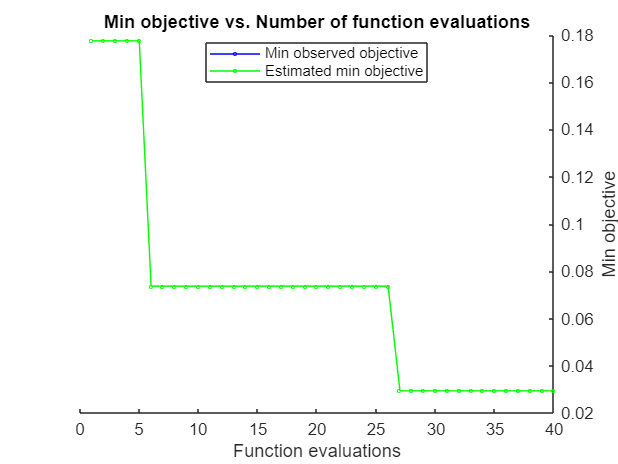

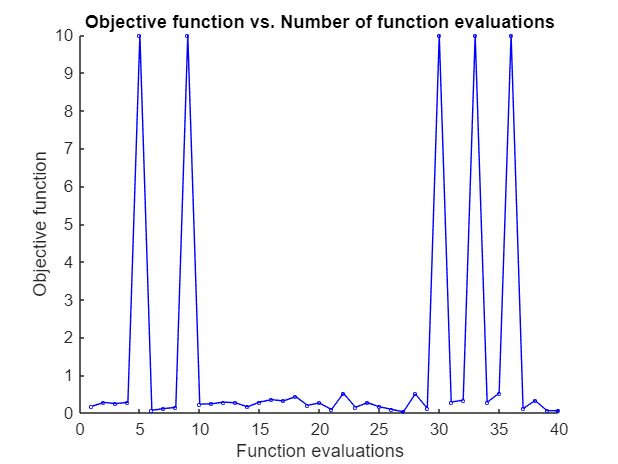

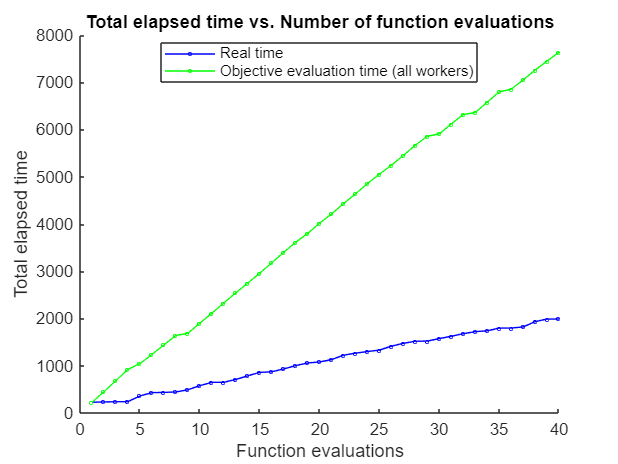

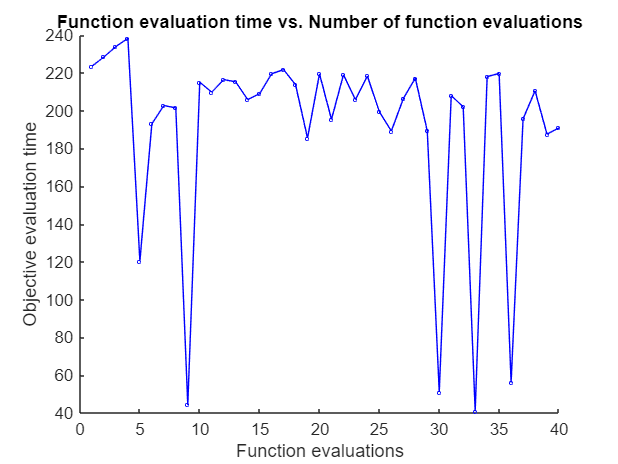

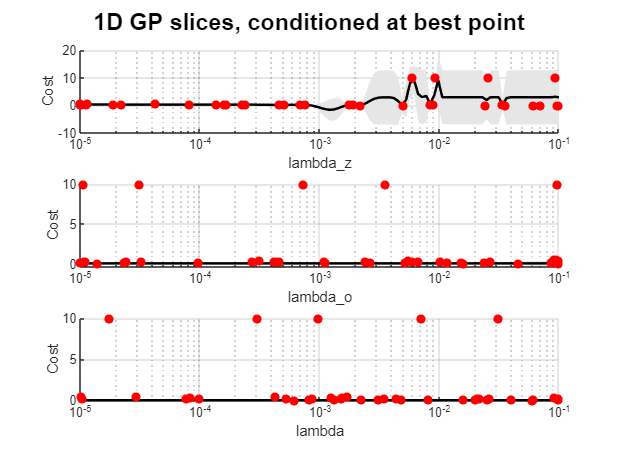

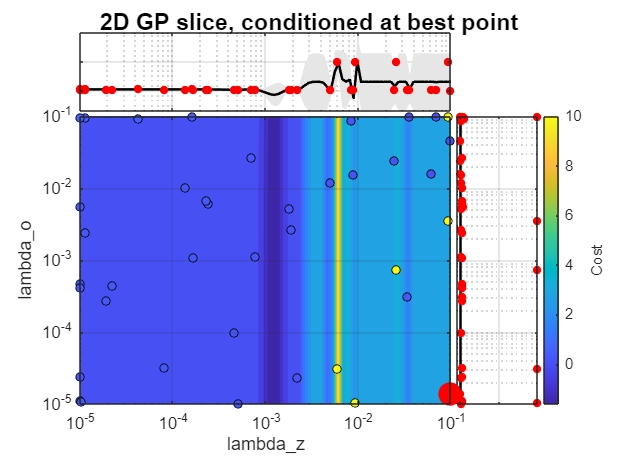


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 40 reached.
Total function evaluations: 40
Total elapsed time: 1989.9072 seconds
Total objective function evaluation time: 7636.9111

Best observed feasible point:
    lambda_z    lambda_o       lambda  
    ________    _________    __________

    0.098622    1.396e-05    0.00062411

Observed objective function value = 0.029375
Estimated objective function value = 0.029375
Function evaluation time = 206.3603

Best estimated feasible point (according to models):
    lambda_z    lambda_o       lambda  
    ________    _________    __________

    0.098622    1.396e-05    0.00062411

Estimated objective function value = 0.029375
Estimated function evaluation time = 159.6793



sorted_Trace = 40×4 table
     lambda_z      lambda_o       lambda        Cost  
    __________    __________    __________    ________

      0.098622     1.396e-05    0.00062411    0.029375
      0.098077      0.045992      0.060542    0.057845
      0.035744      0.099894      0.040018     0.06286
      0.060939      0.015942      0.061364    0.073705
      0.024506      0.024064     0.0048077    0.091254
      0.069837      0.098747      0.019886    0.099432
     0.0022103    2.3495e-05     0.0022473     0.11639
     0.0049981      0.011782     0.0081242     0.11729
     0.0089916      0.015242      0.025145     0.12447
     0.0019063     0.0026567      0.098699     0.14996
    0.00050717    1.0005e-05    0.00082136     0.15145
      0.000462    9.8339e-05     0.0013269      0.1631
     0.0017944     0.0052279     0.0031213     0.16553
    0.000770

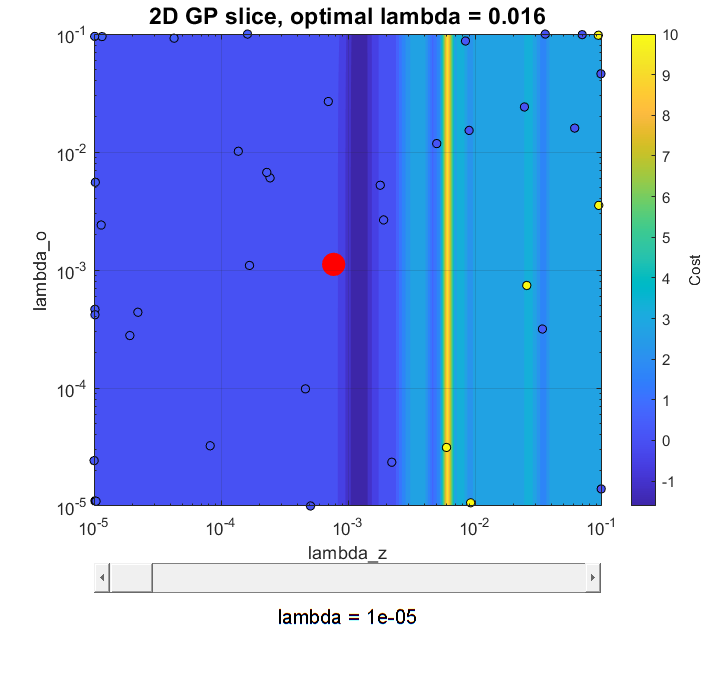

lengthScales = 1.0e+05 *

    0.0000    0.0006    1.5544


gradMu = 1.0e+03 *

   -2.3285   -0.0005   -0.0000


gradSigma2 =     1.7844   -0.0003   -0.0000


x_eval = table2array(X(1, :));
[gradMu, gradSigma2] = gpLocalSensitivity(gp, x_eval)